# Test 2: Two layers, elastic & lateral heterogenities (Enceladus)

In this notebook the tidal response of a **two-layers, elastic body with lateral variations** is computed using LOV3D and compared against: 

- [Berne et al.](https://doi.org/10.1029/2022JE007712) FEM model 

- [Qiin et al.](https://doi.org/10.1093/gji/ggu279) spectral perturbation model 

The script can be used to reproduced Figure 2 of [Rovira-Navarro et al. 2023](https://arxiv.org/abs/2311.15710)

clearvars
clc
set(0,'defaulttextInterpreter','latex') 
mfile_name          = mfilename('fullpath');
if contains(mfile_name,'LiveEditorEvaluationHelper')
    mfile_name=matlab.desktop.editor.getActiveFilename;
end
[pathstr,name,ext]  = fileparts(mfile_name);
cd(pathstr);
cd('..')
addpath(genpath(pwd))

## Interior model

The interior model is based on the **Enceladus model **presented in [Rovira-Navarro et al. 2023](https://arxiv.org/abs/2311.15710). 

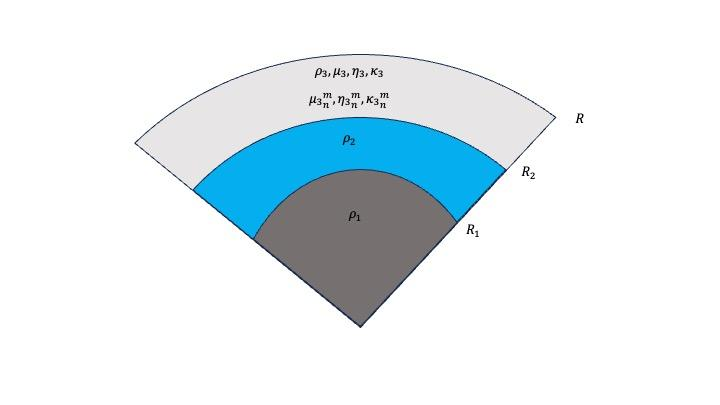

The model parameters are given in non-dimensional variables. The following non-dimensional parameters are used

mu_eff:  $\mu_{eff}=\frac{\mu_3}{g_s\bar\rho R_3}$, 

MaxTime: $\tau=\frac{\omega\eta_3}{\mu_3}$

r_ratio: $\frac{R_3}{R_1}$

rho_r: $\frac{\bar\rho_c}{\rho_3}$, where $\bar\rho_c$ is the average density of layers' 1 and 2

% MEAN VALUES 
G=6.67e-11; 
r_ratio=0.91; %ratio between R3 and R2
rho_ratio=1610/1000; %rho_av/rho_3
Ks_nd=100; %ratio between bulk modulus \kappa and shear modulus \mu  
mu_eff=3.3e9/(4/3*pi*G*252.1e3^2*1610^2); %effective shear modulus
Interior_Model.Delta_rho=0; %density jump between layer 2 and layer 3
% LATERAL VARIATIONS 
n_LV=1; % degree of lateral variations 
m_LV=0; % order of lateral variations 
% the benchmark can be done for n_LV=1, m_LV=0; n_LV=2, m_LV=0; n_LV=1 m_LV=1
% BUILD INTERIOR MODEL 
rho_r=(rho_ratio-1+r_ratio^3)/r_ratio^3;
rho_av=rho_r*r_ratio^3+(1-r_ratio^3);
Gg=3/(4*pi)/mu_eff/rho_av^2;
%Core layer (1), includes both the silicate core and ocean
Interior_Model(1).R0= r_ratio; % core boundary 
Interior_Model(1).rho0= rho_r; % mean core density  
Interior_Model(1).Delta_rho0=0; % density contrast beteen layers 2 and 3, set to 0 for the ice ocean interface
%Ice layer (2)
Interior_Model(2).R0= 1;  %surface radius
Interior_Model(2).rho0=1; %mantle density 
Interior_Model(2).Ks0=Ks_nd; %bulk modulus 
Interior_Model(2).mu0=1;  %shear modulus
Interior_Model(2).Gg=Gg; %non-dimensional gravitational constatant

## Define forcing

The forcing potential is defined

T=1; % the forcing period has been normalized
Forcing(1).Td=T;
Forcing(1).n=2; 
Forcing(1).m=0; 
Forcing(1).F=1;

## Define numerics used to compute the tidal response 

%radial discretization
Numerics.Nlayers = length(Interior_Model); % number of concentric layers. Including the core!
Numerics.method = 'fixed'; % method of setting the radial points per layer
Numerics.Nrbase = 500; % depending on the method this will determine the number of points per layer
%code parallelization
Numerics.parallel_sol = 0; % Use a parfor-loop to call get_Love, either 0 or 1
Numerics.parallel_gen = 0; % Calculate potential coupling files and the propagation inside get_solution using parfor-loops, either 0 or 1
% lateral variations
Numerics.perturbation_order = 3; %maximum order to which couplings are considered
Numerics.load_couplings = 1; % 1=loading of specific file, 2=searches for big enough file
Numerics.Nenergy = 12; % maximum degree to which energy dissipation is expanded 
Numerics.rheology_cutoff = 2; % maximum order of difference (so in log) up to which rheology is still used 
Numerics.coupling_file_location = 'files/couplings/'; % MUST END WITH A '/' , Location where coupling files are saved or should be saved 

[Numerics, Interior_Model] = set_boundary_indices(Numerics, Interior_Model,'verbose');

Inside set_boundary_indices: 
Nrlayer: 0  500
BCindices: 
Nr: 500
 


## Load data for benchmark

The data, stored in ../data/tests/enceladus/, is loaded 

load_file_Q=['data/tests/enceladus/Q_' num2str(n_LV) num2str(m_LV) '.mat'];
load_file_B=['data/tests/enceladus/B_' num2str(n_LV) num2str(m_LV) '.mat'];
load(load_file_Q)
load(load_file_B)
% the following data is loaded 
    % k2_B; k2_Q; degree 2 Love number of the spherically-symmetric model 
    % k_Q; k_B: Love number spectra
        %k_X(1,:): Amplitude of the perturbation in peak to peak variation of the shear modulus [in %] 
        %k_X(2:end,1): Degree of tidal response  
        %k_X(2:end,2): Order of tidal response 
        %k_X(2:end,3): Perturbation order 
        %k_X(2:end,3:end): Amplitude of the tidal response 
    % kD_Q; kD_N: is simply k-k2
% Note that only the m>0 terms are given, with the understanding that the m<0 follow from there
% Some additional variables used: 
l_max=50;
Ynm_stokes.clm=zeros(2*l_max,2*l_max);
Ynm_stokes.slm=zeros(2*l_max,2*l_max);
Ynm_stokes.lmax=2*l_max-1;
Ynm_stokes.clm(n_LV+1,m_LV+1)=1;
[Ynm_zlonlat] = SPH_LatLon(Ynm_stokes);
Ynm_z=Ynm_zlonlat.z;
Delta=max(Ynm_z(:))-min(Ynm_z(:));
% amp is in terms of real spherical harmonics used in Qiin et al. 
% amplitude of lateral variations in peak to peak % variations
amp3=amp*100*Delta/sqrt(4*pi);
% amplitude of lateral variations in complex spherical harmonics
if m_LV==0
    amp2=amp/sqrt(4*pi); 
else
    amp2=amp/sqrt(2)/sqrt(4*pi);
end
amp_B=[1.0000    2.0000    5.0000   10.0000   16.0000   25.0000   35.0000   50.0000];
ind_B=[];
for i=1:length(amp_B)
    ind_B(i)=find(abs(amp_B(i)-amp3)/amp_B(i)<1e-4);    
end

## Compute the tidal response using LOV3D

Compute Tidal Response using LOV3D for the set of interior models specified 

% UNIFORM MODEL 
Interior_Model_U = get_rheology(Interior_Model,Numerics,Forcing);

Viscosity for layer 2 not provided, I will assume the layer is elastic 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 


[Love_Spectra,y_rad]=get_Love(Interior_Model_U,Forcing,Numerics,'verbose');

Obtaining Couplings....
Only uniform layers so coupling matrix is zero
------------- INTERIOR MODEL ----------- 
AVERAGE PROPERTIES (dimensional)
Layer#     R[m]    rho[kg.m^{-3}]    mu[Pa]    K[Pa]    eta[Pa.s]
1    9.10000e-01    1.80948e+00    0    -
2    1.00000e+00    1.00000e+00    1.00000e+00    1.00000e+02 
AVERAGE PROPERTIES (non-dimensional)
Layer#     R[-]    rho[-]    mu[-]    K [-]     eta[-]
1    0.91    1.8095    0    -
2    1    1    1    100 NaN
RHEOLOGY  VARIATIONS
Shear Modulus
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
2    (0,0)   0.00000e+00
Bulk Modulus
Layer#      (n,m)           amplitude[K_n^m/K_0^0]
2    (0,0)   0.00000e+00
Viscosity
Layer#      (n,m)          amplitude[eta_n^m/eta_0^0]
2    (0,0)   0.00000e+00
Complex Shear Modulus
Layer#      (n,m)         amplitude[\hat\mu_n^m/mu_0^0]
2    (0,0)    0.00000e+00
 
----------- FORCING ----------
TIDAL POTENTIAL
Period [s]
1.00000e+00
(n,m)
(2,0)
 
----------

iforcing=find(Love_Spectra.n==Forcing.n & Love_Spectra.m==Forcing.m);
k2_uniform=Love_Spectra.k(iforcing);    
% LATERAL VARIATIONS
for kk=1:length(amp)
    % build interior model 
    % write lateral variations in terms of complex spherical harmonics
    if m_LV==0
        Interior_Model(2).mu_variable(1,1)=n_LV;
        Interior_Model(2).mu_variable(1,2)=m_LV;
        Interior_Model(2).mu_variable(1,3)=amp(kk)/sqrt(4*pi);
    else
        Interior_Model(2).mu_variable(1,1)=n_LV;
        Interior_Model(2).mu_variable(1,2)=m_LV;
        Interior_Model(2).mu_variable(1,3)=amp(kk)/sqrt(2)/sqrt(4*pi);

        Interior_Model(2).mu_variable(2,1)=n_LV;
        Interior_Model(2).mu_variable(2,2)=-m_LV;
        Interior_Model(2).mu_variable(2,3)=(-1)^m_LV*amp(kk)/sqrt(2)/sqrt(4*pi);
    end
    % set interior structure in the right format for the get_Love
    Interior_Model_U= get_rheology(Interior_Model,Numerics,Forcing);
    % obtain tidal response 
    [Love_Spectra,y_rad]=get_Love(Interior_Model_U,Forcing,Numerics);
    % store Love numbers
    iforcing=find(Love_Spectra.n==Forcing.n & Love_Spectra.m==Forcing.m);
    k2ST=Love_Spectra.k;
    k2ST(iforcing)=Love_Spectra.k(iforcing)-k2_uniform;
    k2(:,kk)=k2ST;
end

Viscosity for layer 2 not provided, I will assume the layer is elastic 
Viscosity for layer 2 not provided, I will assume the layer is elastic 
Viscosity for layer 2 not provided, I will assume the layer is elastic 
Viscosity for layer 2 not provided, I will assume the layer is elastic 
Viscosity for layer 2 not provided, I will assume the layer is elastic 
Viscosity for layer 2 not provided, I will assume the layer is elastic 
Viscosity for layer 2 not provided, I will assume the layer is elastic 
Viscosity for layer 2 not provided, I will assume the layer is elastic 
Viscosity for layer 2 not provided, I will assume the layer is elastic 
Viscosity for layer 2 not provided, I will assume the layer is elastic 
Viscosity for layer 2 not provided, I will assume the layer is elastic 
Viscosity for layer 2 not provided, I will assume the layer is elastic 
Viscosity for layer 2 not provided, I will assume the layer is elastic 
Viscosity for layer 2 not provided, I will assume the layer is e

k2_all=k2;

## Compare results

% reorder the Love numbers
n_s=Love_Spectra.n;
m_s=Love_Spectra.m;
order=Love_Spectra.order;
k2=k2_all;

ind=find(n_s==0 & m_s==0); 
if isempty(ind)==0
    n_s(ind)=[];
    m_s(ind)=[];
    order(ind)=[];
    k2(ind,:)=[];
end

ind=find(n_s==1); 
if isempty(ind)==0
    n_s(ind)=[];
    m_s(ind)=[];
    order(ind)=[];
    k2(ind,:)=[];
end

[order, ind]=sort(order);
n_s=n_s(ind);
m_s=m_s(ind); 
k2=k2(ind,:);
ind=find(abs(k2(:,end))>0);
n_s=n_s(ind);
m_s=m_s(ind); 
k2=k2(ind,:);
order=order(ind);
ind=find(m_s>=0);
n_s=n_s(ind);
m_s=m_s(ind); 
k2=k2(ind,:);
order=order(ind);

% prepare colorbar
first_order_ind=find(order==1);
second_order_ind=find(order==2);
third_order_ind=find(order==3);
order_1_c=cmocean('dense',length(first_order_ind)+2);
order_2_c=cmocean('algae',length(second_order_ind)+2);
order_3_c=cmocean('matter',length(third_order_ind)+2);
color_lines=[order_1_c(2:end-1,:); order_2_c(2:end-1,:); order_3_c(2:end-1,:) ];

k_M=zeros(length(n_s)+2,3+length(amp));
k_M(3:end,1)=n_s; 
k_M(3:end,2)=m_s;
k_M(1,4:end)=amp3;
k_M(2,1)=Forcing.n;
k_M(2,2)=Forcing.m;
k_M(2,4:end)=k2_uniform;
k_M(3:end,3)=order;
k_M(3:end,4:end)=k2;
kD_M=k_M; 
ind_f=find(k_M(3:end,1)==Forcing.n & k_M(3:end,2)==Forcing.m);
if isempty(ind_f)==0
    k_M(2+ind_f,4:end)= kD_M(2+ind_f,4:end)+k2_uniform; 
end

## Compute differences

%% compute error & prepare lengend
kk=1; 
le2=[];
error1=[];
error2=[];
error3=[];
error4=[];
error5=[];

error1_B=[];
error2_B=[];
error3_B=[];
error4_B=[];
error5_B=[];

y_ticks=1; 
save_plot=0; 

amp_B=[1.0000    2.0000    5.0000   10.0000   16.0000   25.0000   35.0000   50.0000];
ind_B=[];
for i=1:length(amp_B)
    ind_B(i)=find(abs(amp_B(i)-amp3)<1e-5);    
end
ind_B=3+ind_B;
for i=2:size(k_M,1)
    ind_aux=find(k_M(i,1)==k_Q(2:end,1) & k_M(i,2)==k_Q(2:end,2) & k_M(i,3)==k_Q(2:end,3));
    ind_aux2=find(k_M(i,1)==k_B(2:end,1) & k_M(i,2)==k_B(2:end,2) & k_M(i,3)==k_B(2:end,3));
    if isempty(ind_aux)==0
        ind_aux=ind_aux+1;
        ind_aux2=ind_aux2+1;
        le2{kk}=['$(' num2str(k_M(i,1)) ',' num2str(k_M(i,2)) ')$'];
        %(k_R-k_Q)/k_Q
        error1(kk,:)=[k_M(i,1:3) ((k_M(i,4:end)-k_Q(ind_aux,4:end))./k_M(i,4:end))];
        error1_B(kk,:)=[k_M(i,1:3) ((k_M(i,ind_B)-k_B(ind_aux2,4:end))./k_M(i,ind_B))];        
        %(\Delta k_R-\Delta k_Q)/\Delta k_Q
        error2(kk,:)=[k_M(i,1:3) ((kD_M(i,4:end)-kD_Q(ind_aux,4:end))./kD_M(i,4:end))];
        error2_B(kk,:)=[k_M(i,1:3) ((kD_M(i,ind_B)-kD_B(ind_aux2,4:end))./kD_M(i,ind_B))];
        %(k_R/k2-k_Q/k2)/k_Q/2
        error3(kk,:)=[k_M(i,1:3) ((k_M(i,4:end)/k2_uniform-k_Q(ind_aux,4:end)/k2_Q)./k_M(i,4:end)*k2_uniform)];
        error3_B(kk,:)=[k_M(i,1:3) ((k_B(ind_aux2,4:end)/k2_B-k_M(i,ind_B)/k2_uniform)./k_M(i,ind_B)*k2_uniform)];        
        %(\Delta k_R/k2-\Delta k_Q/k2)/\Delta k_Q/k2
        error4(kk,:)=[k_M(i,1:3) ((kD_M(i,4:end)/k2_uniform-kD_Q(ind_aux,4:end)/k2_Q)./kD_M(i,4:end)*k2_uniform)];
        error4_B(kk,:)=[k_M(i,1:3) ((kD_M(i,ind_B)/k2_uniform-kD_B(ind_aux2,4:end)/k2_B)./kD_M(i,ind_B)*k2_uniform)];
        % error 5       
        error5(kk,:)=[k_M(i,1:3) ((kD_Q(ind_aux,4:end)-kD_M(i,4:end))./kD_M(i,4:end))*100];
        error5_B(kk,:)=[k_M(i,1:3) ((kD_B(ind_aux2,4:end)-kD_M(i,ind_B))./kD_M(i,ind_B))*100];
        
        kk=kk+1;
    end
end
error_u=(k2_Q-k2_uniform)/k2_uniform*100; 

## Make figures

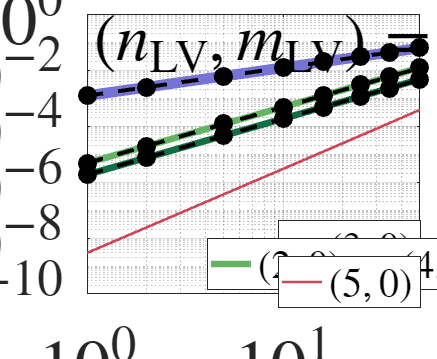

%% MAKE FIGURES FOR BENCHMARK
% plot k/k2 uniform 
fig=figure;
set(fig, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 0.65, 0.95]);
ax1 = axes(fig);
ax1.Position=[0.200 0.180 0.76 0.78];
plots_fig=[];
ll=1; 
% Rovira et al. 
for i=3:size(k_M,1)
    plots_fig(ll)=plot(amp3,abs(kD_M(i,4:end))/k2_uniform,'LineWidth',8-3*(kD_M(i,3)-1),'color',color_lines(i-2,:));
    le{ll}=['$(' num2str(k_M(i,1)) ',' num2str(k_M(i,2)) ')$'];
    ll=ll+1;
    hold on
end
% Qin et al. 
for i=3:size(k_Q,1)
    plot(amp3,abs(kD_Q(i,4:end))/k2_Q,'Color','k','LineWidth',3,'LineStyle','--')
    hold on 
end

for i=3:size(k_B,1)
    scatter(amp_B,abs(kD_B(i,4:end))/k2_B,200,[0 0 0],'filled')    
    hold on 
end
set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')
ylim([1e-10 1])
xlim([abs(amp3(1)) abs(amp3(end))])
set(gca,'FontSize',55)
ax1.XTick=[1e-3 1e-2 1e-1 1 1e1 1e2];
ax1.YTick=[1e-10 1e-8 1e-6 1e-4 1e-2 1e0];
grid on
x_label=['$100 \mid \Delta \mu/\mu_0 \mid$  [\%]'];
set(ax1,'TickLabelInterpreter','latex')
hold on 
tit=['$\left(n_\textrm{LV},m_\textrm{LV}\right)=\left(' num2str(n_LV) ',' num2str(m_LV) '\right)$'];
hold on
text(ax1,1,1e-1,tit,'Interpreter','latex','FontSize',50)
xlabel(x_label);
set(gcf,'color','w');
box on
a1=axes('position',get(gca,'position'),'visible','off');
leg1=legend(a1,plots_fig(first_order_ind),le(first_order_ind),'Position',[0.65 0.29 0.3 0.05],'units','normalized','orientation','horizontal','FontSize',30,'interpreter','latex');
a2=axes('position',get(gca,'position'),'visible','off');
leg2=legend(a2,plots_fig(second_order_ind),le(second_order_ind),'Position',[0.65 0.24 0.3 0.05],'units','normalized','orientation','horizontal','FontSize',30,'interpreter','latex');
a3=axes('position',get(gca,'position'),'visible','off');
set(a3,'FontSize',40)
leg2=legend(a3,plots_fig(third_order_ind),le(third_order_ind),'Position',[0.65 0.19 0.3 0.05],'units','normalized','orientation','horizontal','FontSize',30,'interpreter','latex');
y_label=['$\mid\Delta k_{'  num2str(Forcing.n) ',' num2str(Forcing.m) '}^{n,m}\mid/k_{' num2str(Forcing.n) '}^u$'];
ylabel(ax1,y_label);




%% Difference
error=abs(error4(2:end,:));
error_B=abs(error4_B(2:end,:));
fig=figure;
set(fig, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 0.65, 0.95]);
ax1 = axes(fig);
ax1.Position=[0.200 0.180 0.76 0.78];
% plot error
le=[];
for i=1:size(error,1)
    plots_fig(i)=plot(amp3,error(i,4:end)*100,'LineWidth',8-3*(error(i,3)-1),'color',color_lines(i,:))
    hold on
    %plot(amp3,error_B(i,4:end)*100,'LineWidth',8-3*(error(i,3)-1),'color',color_lines(i,:),'LineStyle','--')
    scatter(amp_B,error_B(i,4:end)*100,200,color_lines(i,:),'filled')
    le{i}=['(' num2str(error(i,1)) ',' num2str(error(i,2)) ')'];
end

plots_fig =    14.0001   11.0001   12.0001   13.0001


plots_fig =    14.0001   15.0001   12.0001   13.0001


plots_fig =    14.0001   15.0001   16.0001   13.0001


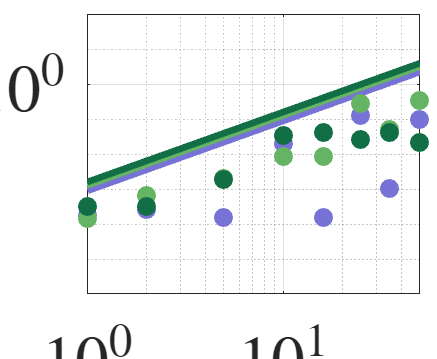

grid on
xlim([abs(amp3(1)) abs(amp3(end))])
ylim([1e-6 1e2])
x_label=['$100\mid \Delta \mu/\mu_0^0 \mid$  [\%]'];
xlabel(x_label);
ax1.XTick=[1e-3 1e-2 1e-1 1 1e1 1e2];
set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')
set(gca,'FontSize',50)
set(ax1,'TickLabelInterpreter','latex')
set(gcf,'color','w');
y_label=['Difference [\%]'];
ylabel(ax1,y_label);